L = 0.127

L = 0.1270



v_a1 = -17:0.1:31;
v_a2 = 90-27:0.1:90+27;

n_a1 = size(v_a1,2);
n_a2 = size(v_a2,2);

J11 = zeros(n_a1,n_a2);
J22 = J11;
Jmix = J11;

[mesh_a1,mesh_a2] = meshgrid(v_a1,v_a2);

for i = 1:size(v_a1,2)
    for j = 1:size(v_a2,2)
        a1 = deg2rad(v_a1(i));
        a2 = deg2rad(v_a2(j));
        
        [x, y, p1 , p2, error] = direct_kinematics(a1,a2);
        [J11(i,j), Jmix(i,j), ~, J22(i,j), error_mj] = mass_jacobian(x,y,false);
        
        

    end
end

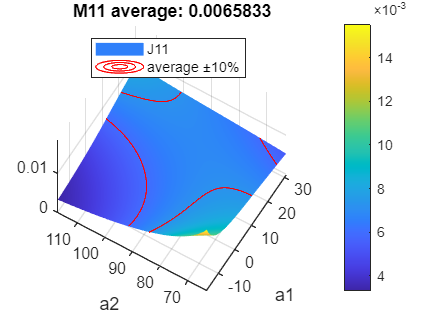

figure;
J11_v = reshape(J11,1,[]);
J11_mean = mean(J11_v);
% J11_m_mat = J11_mean*ones(n_a1,n_a2);
surf(mesh_a1,mesh_a2,J11',"EdgeColor","none");
colorbar
hold on
contour3(mesh_a1,mesh_a2,J11',[J11_mean*0.9 J11_mean*1.1],"red")
hold off
title("M11 average: "+J11_mean);
xlabel("a1")
ylabel("a2")
zlim([0 1.2*max(J11_v)])
daspect([1 1 0.0004])
view([-59.1423 60.8167])
legend(["J11", "average ±10%"], "Position", [0.2343 0.7709 0.3077, 0.1036])

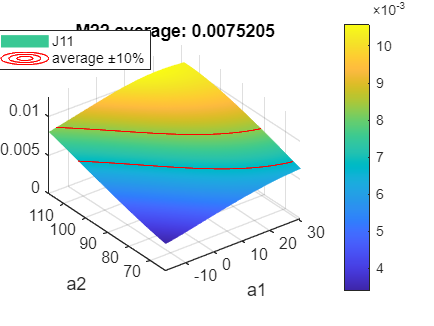




figure;
J22_v = reshape(J22,1,[]);
J22_mean = mean(J22_v);
surf(mesh_a1,mesh_a2,J22',"EdgeColor","none");
colorbar
hold on
contour3(mesh_a1,mesh_a2,J22',[J22_mean*0.9 J22_mean*1.1],"red")
hold off
title("M22 average: "+J22_mean);
xlabel("a1")
ylabel("a2")
zlim([0 1.2*max(J22_v)])
daspect([1 1 0.0004])
legend(["J11", "average ±10%"], "Position", [0.0155 0.7948 0.3077, 0.1036])

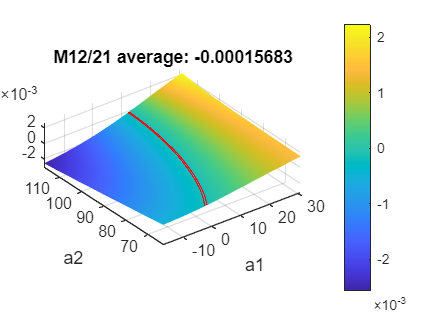





figure;
Jd_v = reshape(Jmix,1,[]);
Jd_mean = mean(Jd_v);
surf(mesh_a1,mesh_a2,Jmix',"EdgeColor","none");
colorbar
hold on
contour3(mesh_a1,mesh_a2,Jmix',[Jd_mean*0.9 Jd_mean*1.1],"red")
hold off
title("M12/21 average: "+Jd_mean);
xlabel("a1")
ylabel("a2")
zlim([ 1.2*min(Jd_v) 1.2*max(Jd_v)])
daspect([1 1 0.0004])